# anti-Winner-take-all (anti-WTA) in L2/3, buit L5 in ordered pattern

clear;
clc;
addpath('../funcs');
% load ../../data/allpsd_0_0.5_0_0.05_Iattn_0.02.mat;
load ../../data/all5000_levelMethod2_0_0.5_0_0.05_Iattn_0.02.mat;
levelSheet = levelSheet*1000;

pops = ["1L2/3E","1L2/3I","1L4E","1L4I","1L5E","1L5I","1L6E","1L6I"];
conds = ["original", "S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"];

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 10;
steps = size(levelSheet,1);
pop = 5;


## rule out by PSD peaks

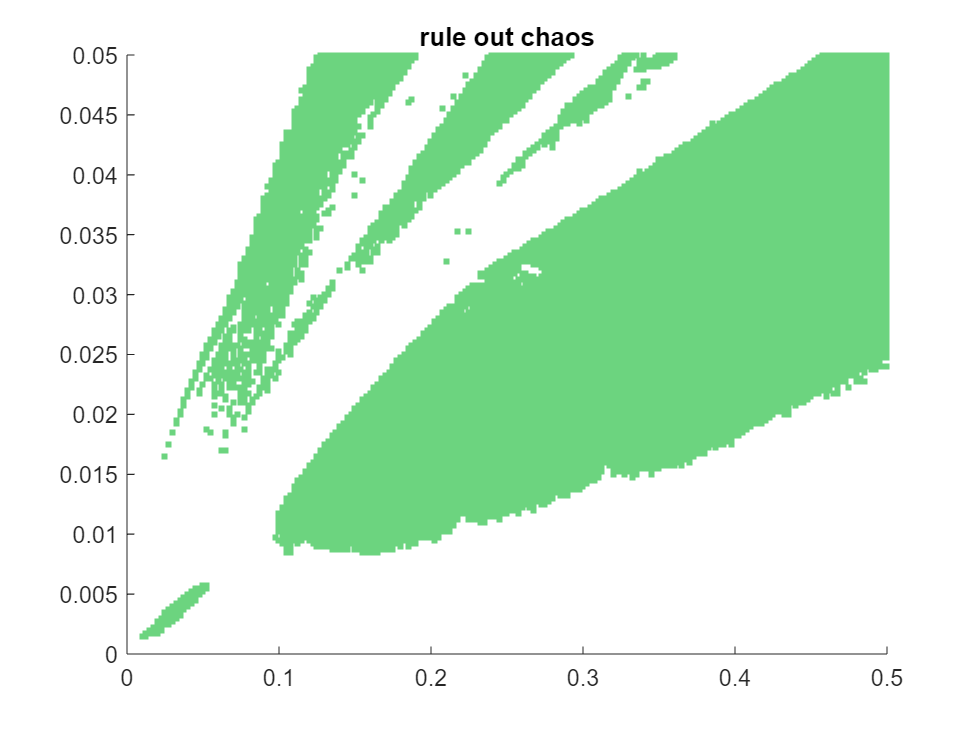

ruleOut = zeros(steps,steps);
maxPks = 4;

for i = 1:steps
    for j = 1:steps
        cond0 = psdPeaksSheet(i,j,pop,1); cond1 = psdPeaksSheet(i,j,pop,2); cond2 = psdPeaksSheet(i,j,pop,3);
        cond3 = psdPeaksSheet(i,j,pop,3); cond4 = psdPeaksSheet(i,j,pop,5); cond5 = psdPeaksSheet(i,j,pop,6);
        tmp = max([cond0 cond1 cond2 cond3 cond4 cond5]);
        if tmp<=maxPks && tmp>=1 
            ruleOut(i,j) = 1;
        end
    end
end

ruleOut = ruleOut == 1;

figure();
for i = 1:steps
    x = Delta_e(ruleOut(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("rule out chaos");

## L5 in order: by mean of firing rate

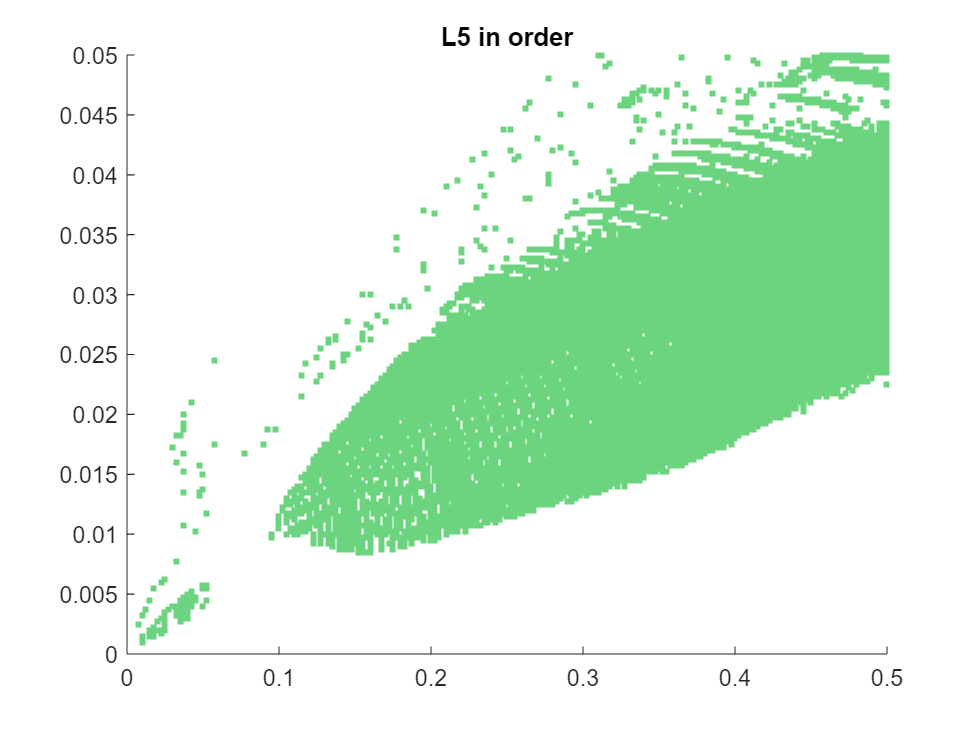

order = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            order(i,j) = 1;
        end
    end
end

order = order == 1;

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L5 in order");

## L5 in order: by mean of envelop of firing rate

% load ../../data/allpsd_0_0.5_0_0.05_Iattn_0.02.mat;
% order = zeros(steps,steps);
% 
% for i = 1:steps
%     for j = 1:steps
%         cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
%         cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
%         if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
%             order(i,j) = 1;
%         end
%     end
% end
% 
% order = order == 1;
% 
% figure();
% for i = 1:steps
%     x = Delta_e(order(steps+1-i,:));
%     y = Delta_i(i)*ones(length(x),1);
%     s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
%     hold on;
% end
% hold off;
% axis([0 0.5 0 0.05]);
% title("L5 in order (envelop)");

## L2/3 WTA

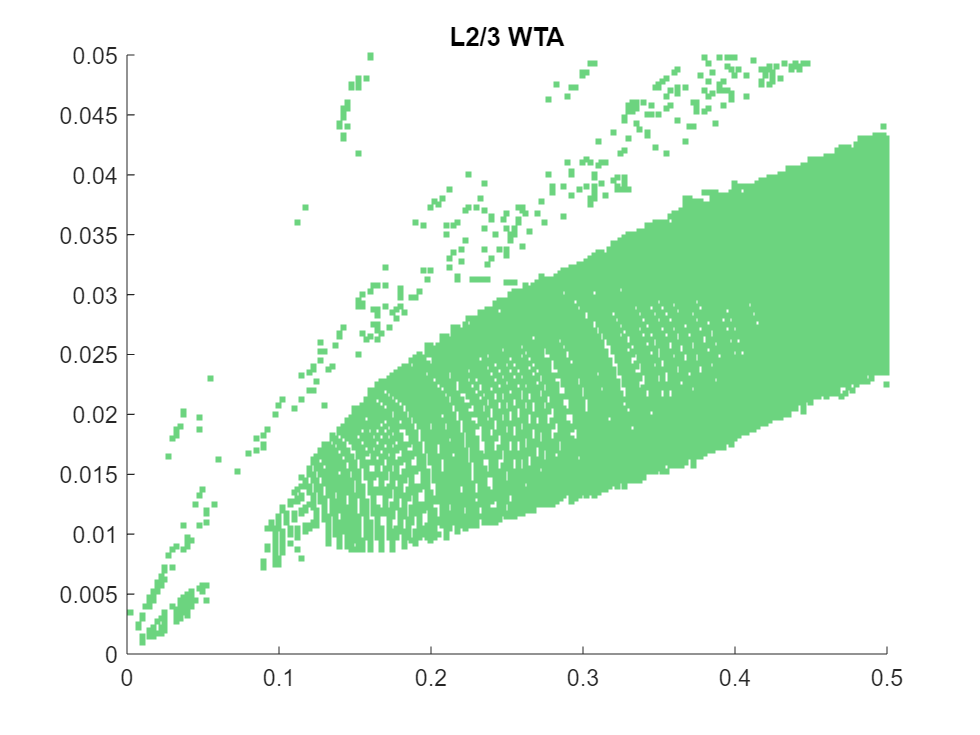

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L2/3 WTA");

## L2/3 anti-WTA: sensory

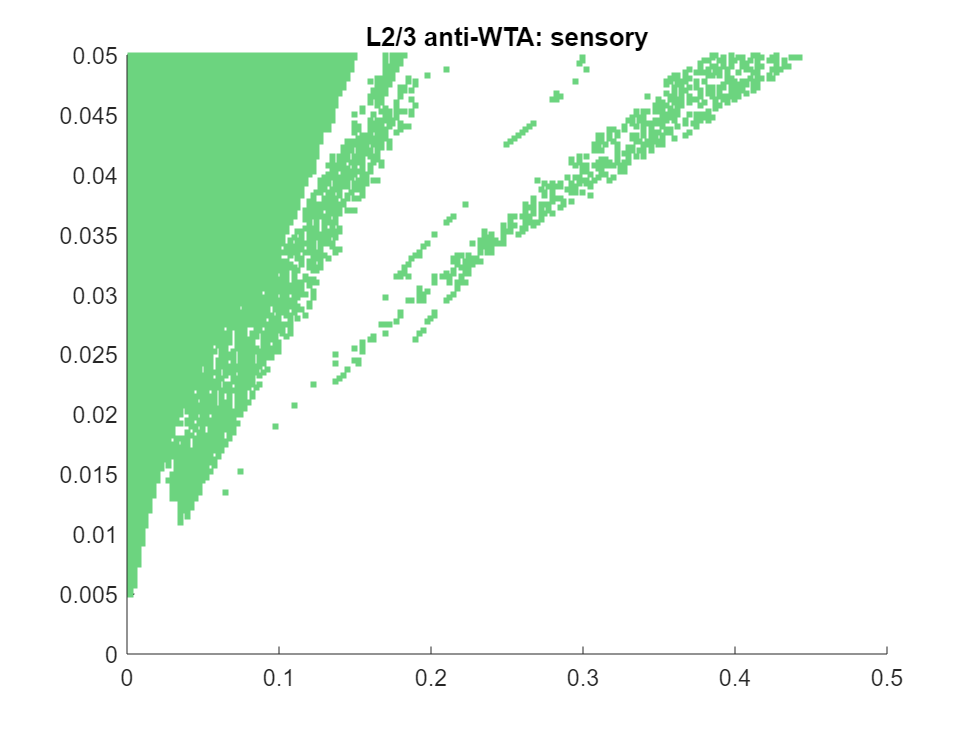

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1<cond2
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L2/3 anti-WTA: sensory");

## L2/3 anti-WTA: attention

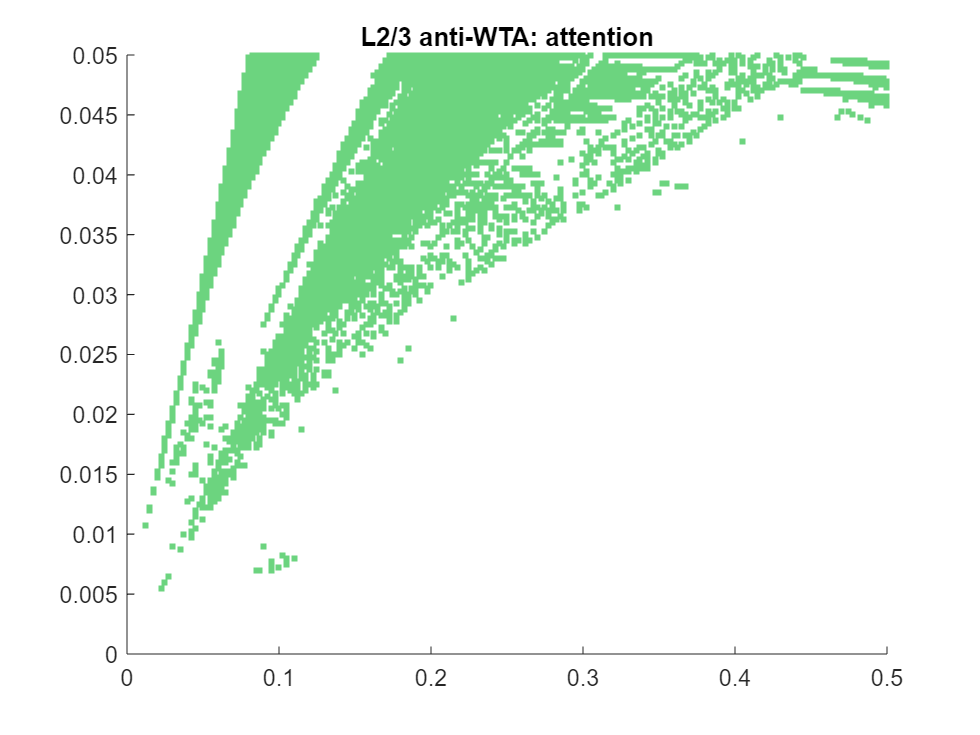

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond4<cond3 && cond3<cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L2/3 anti-WTA: attention");

## combine L5 in order and L2/3 anti-WTA attention

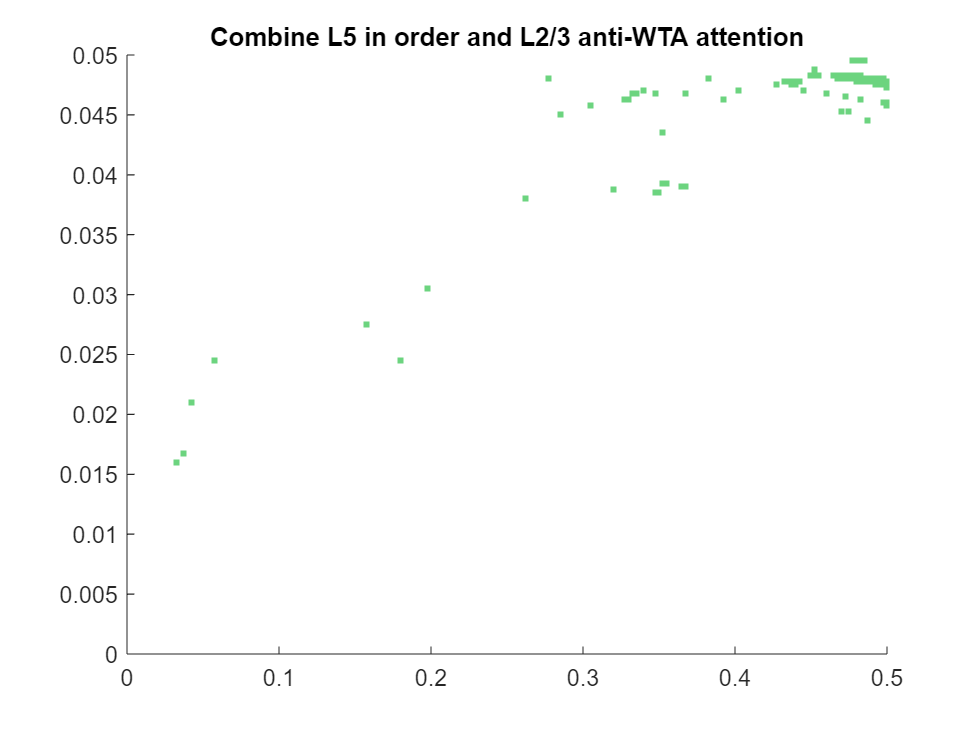

pop = 5;

order = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            order(i,j) = 1;
        end
    end
end

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond4<cond3 && cond3<cond5
            antiWTA(i,j) = 1;
        end
    end
end

combine = order.*antiWTA;
combine = combine == 1;

figure();
for i = 1:steps
    x = Delta_e(combine(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Combine L5 in order and L2/3 anti-WTA attention");